**Exercise 1**

Implement the Modified Euler method in a function.

Test it on $\frac{dx}{dt} = -0.5x$ with $x(0)= 1$ for $0 \leq t \leq 20$ again.

Try using $h = 1$, $h = 3$, and $h = 4.2$ to see if it is stable.

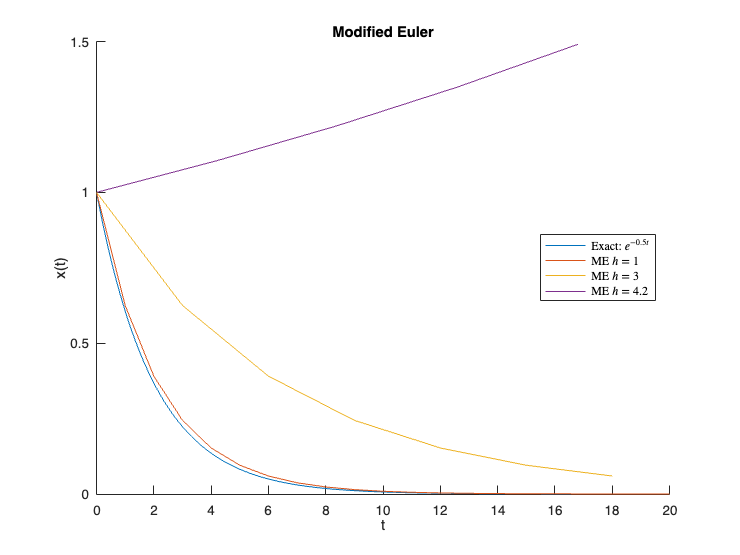

clear; close all; clc;

%ODE: dx/dt = -0.5 x
f  = @(t,x) -0.5*x;
x0 = 1;
t0 = 0; 
tEnd = 20;

hValues = [1, 3, 4.2];

figure;
hold on;

tFine = linspace(t0, tEnd, 1000);
plot(tFine, exp(-0.5*tFine));

%Modified Euler for each h
for h = hValues
    t = t0:h:tEnd;
    
    x = odeME(f, x0, t);
    plot(t, x);
end

legend("Exact: $e^{-0.5t}$", "ME $h = 1$", "ME $h = 3$", "ME $h = 4.2$", "Location", "best", "interpreter", "latex");
xlabel("t");
ylabel("x(t)");
title("Modified Euler");
hold off;

**Exercise 2**

Implement the 4th order Runge-Kutta method in a function.

Test it on the same function as before.

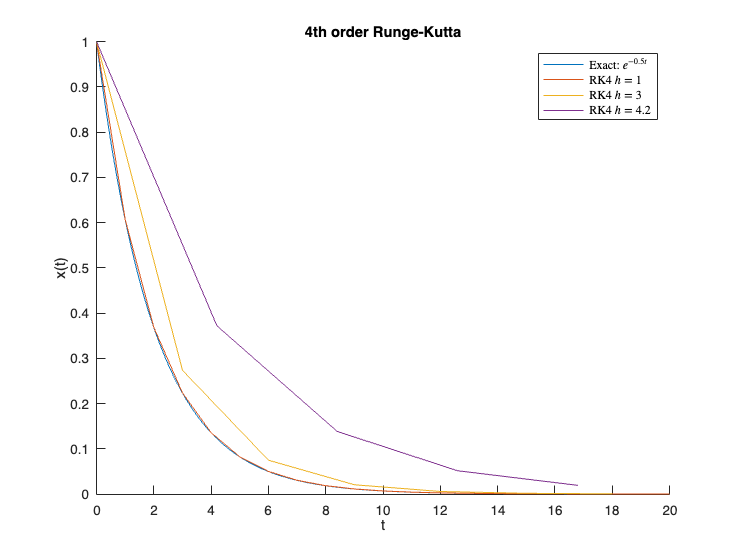

figure;
hold on;

plot(tFine, exp(-0.5*tFine));

%RK4 for each h
for h = hValues
    t = t0:h:tEnd;
    
    x = odeRK4(f, x0, t);
    plot(t, x);
end

legend("Exact: $e^{-0.5t}$", "RK4 $h = 1$", "RK4 $h = 3$", "RK4 $h = 4.2$", "Location", "best", "interpreter", "latex");
xlabel("t");
ylabel("x(t)");
title("4th order Runge-Kutta");
hold off;

**Exercise 3**

Given a nonlinear ODE + IC:


$$\frac{dv}{dt} = - 0.2 v - 2 \cos (2t) v^2, \quad v(0) = 1$$


Solve it for $t = 0 - 7s$ using

- Matlabs `ode45`

- Forward Euler

- Backward Euler

- Runge-Kutta 4th order

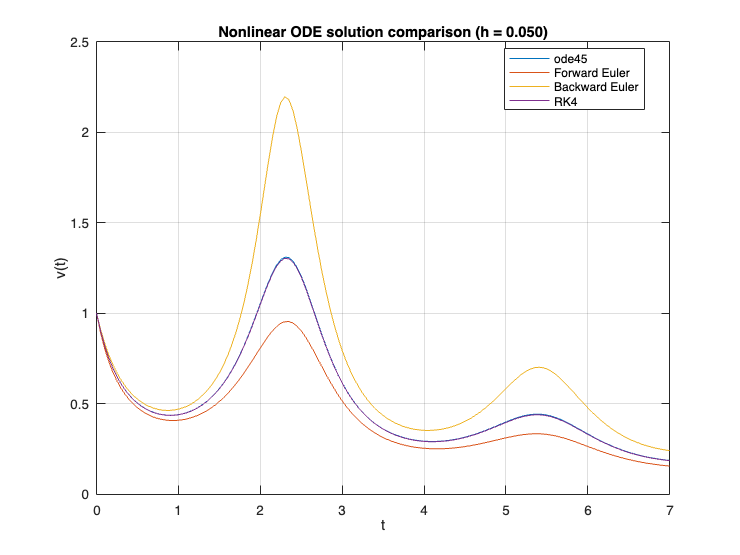

f = @(t,v) -0.2*v - 2*cos(2*t).*v.^2;
v0 = 1;
t0 = 0;
tEnd = 7;

h = 0.05;
t = (t0:h:tEnd)';

[t45, v45] = ode45(f, t, v0);
vFE  = odeFE(f,  v0, t);
vBE  = odeBE(f,  v0, t);
vRK4 = odeRK4(f, v0, t);

figure;
plot(t45, v45); hold on;
plot(t, vFE);
plot(t, vBE);
plot(t, vRK4);

grid on;
xlabel("t");
ylabel("v(t)");
title(sprintf("Nonlinear ODE solution comparison (h = %.3f)", h));
legend("ode45", "Forward Euler", "Backward Euler", "RK4", "Location", "best");

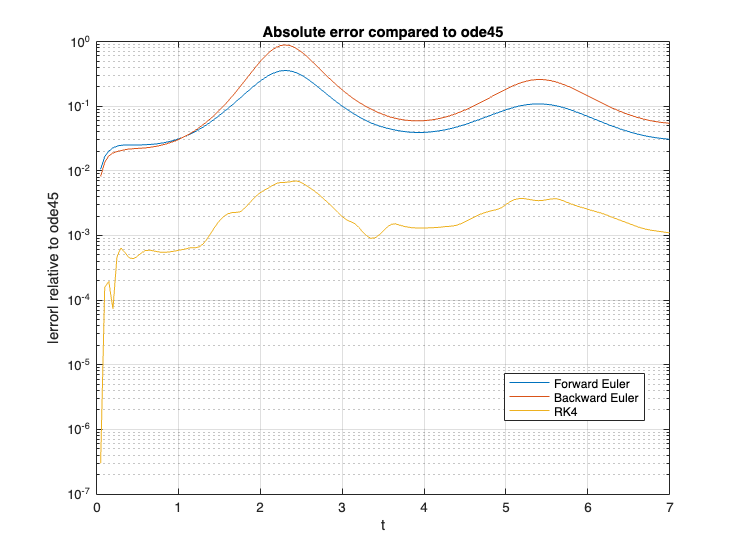


% Error of own methods compared to ODE45
errFE  = abs(vFE  - v45);
errBE  = abs(vBE  - v45);
errRK4 = abs(vRK4 - v45);

figure;
semilogy(t, errFE); hold on;
semilogy(t, errBE);
semilogy(t, errRK4);
grid on;
xlabel("t");
ylabel("|error| relative to ode45");
title("Absolute error compared to ode45");
legend("Forward Euler", "Backward Euler", "RK4", "Location", "best");